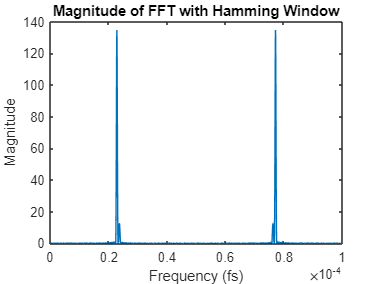

%q4
data = load('Exp4Data1.txt');
fs = 1; 
T=1/fs;
t=0:T:duration-T;
N = length(data);

%q4(a)
window = hamming(N);
data_window = data .* window';

n= 10000;
fft_new = fft(data_window, n);
freq = (0:n-1) * (fs / n);
freq_normalized = freq / n;
figure;
plot(freq_normalized, abs(fft_new));
title('Magnitude of FFT with Hamming Window');
xlabel('Frequency (fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_new), 2);
frequencies = freq_normalized(max_indices);
disp(['Estimated Frequencies using Hamming Window: ', num2str(sort(frequencies))]);

Estimated Frequencies using Hamming Window: 2.281e-05   7.719e-05


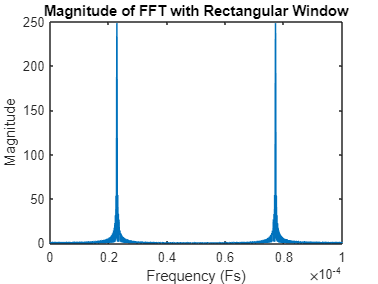


%q4(b)
window_rect = rectwin(N);
data_window_rect = data .* window_rect';
fft_rect = fft(data_window_rect, n);
figure;
plot(freq_normalized, abs(fft_rect));
title('Magnitude of FFT with Rectangular Window');
xlabel('Frequency (Fs)');
ylabel('Magnitude');


[~, max_indices] = maxk(abs(fft_rect), 2);
frequencies1 = freq_normalized(max_indices);
disp(['Estimated Frequencies using Rectangular Window: ', num2str(sort(frequencies1))]);

Estimated Frequencies using Rectangular Window: 2.281e-05   7.719e-05
